# Setup and Configuration

**Date: **25.07.02

**Corresponding Author: **Kyoungseok Han (kyoungsh@hanyang.ac.kr), Hanyang University

**Author: **Junghyo Kim (hyo05122@hanyang.ac.kr), Hanyang University

**Description: **This script offers a  simplified implementation for understanding the application of **GPMPC** in autonomous driving.

**Requirements:**

`- MATLAB R2020b or later`

`- Optimization Toolbox`

`- Statistics and Machine Learning Toolbox (for K-means clustering)`

`- Parallel Computing Toolbox (Optionally, `**Improves **`fmincon`** performance (activate with **`'UseParallel', true`**).**

This first section prepares the MATLAB environment. It clears the workspace of any existing variables, closes all figures.  

clc; clear; close all;

# PART 1: DATA GENERATION

### 1.1 System and MPC Parameters Definition

The objective of this part is to collect data that captures the errors originating from **"model mismatch"**—the difference between the simplified model used for MPC predictions and the more complex, true dynamics of the system (the "plant"). This error data is the foundation for training the GP models in Part 2. 

Here, we define all fundamental parameters for the vehicle system, **MPC** controller, and the simulation. The state vector $x
$ represents the vehicle's condition, and the input vector $u$ represents the control commands. They are defined as:

***State Vector: ***$x = [p_x, p_y, v, \psi, \delta]^T$ (where $p_x
$ is x-position, $p_y$ is y-position, $v$ is velocity, $\psi$ is heading angle, and $\delta$ is steering angle) 

***Input Vector:*** $u = [F_{lon},   \dot{\delta}]^T$ (where $F_{lon}$ is the longitudinal force and $\dot{\delta}$ is the steering rate)

% 'PART 1: DATA GENERATION
[p, I] = utilityFunctions('defineSystemAndMPCParams');

% Display key parameters in a single block
fprintf(['   Key parameters:\n' ...
         '   - Sampling time: %.2f s\n' ...
         '   - Prediction horizon: %d steps\n' ...
         '   - Simulation length: %d steps\n' ...
         '   - Number of state variables: %d\n' ...
         '   - Number of input variables: %d\n\n'], ...
         p.timeStep, p.horizonLength, p.simLength, length(I.states), length(I.inputs));

   Key parameters:
   - Sampling time: 0.10 s
   - Prediction horizon: 5 steps
   - Simulation length: 200 steps
   - Number of state variables: 5
   - Number of input variables: 2



### **1.2 Racing Track Definition**

This step generates the reference path for the vehicle to follow. We use the `pathFunctions` helper to define an elliptical race track, which provides the necessary geometric information like coordinates, heading, and curvature for the controller.

reference_path = pathFunctions('defineRacingTrack', 'ellipse');
fprintf('   Elliptical track generated (number of points: %d)\n\n', length(reference_path.x));

   Elliptical track generated (number of points: 201)



### **1.3 Data Collection Simulation**

We now run a simulation using a standard MPC to drive the vehicle and collect data on the model error. At each time step $k$, the MPC predicts the next state $x_{k+1}^{pred}$ using its internal model. This prediction is then compared to the actual state $x_{k+1}^{real}$ that results from applying the control input to the more accurate plant model. The difference is the model error $d_k$. This process allows us to build a dataset of input-output pairs that the GP can learn from:

***GP Input:*** $X_k = [x_k^T, u_k^T]^T$ (The state and input that caused the error)

***GP Target:*** $Y_k = d_k = x_{k+1}^{real} - x_{k+1}^{pred}$ (The resulting model error)

This entire simulation and data logging process is handled by the `runDataCollectionSimulation` function.

      Simulation progress: 50 / 200
      Simulation progress: 100 / 200
      Simulation progress: 150 / 200
      Simulation progress: 200 / 200


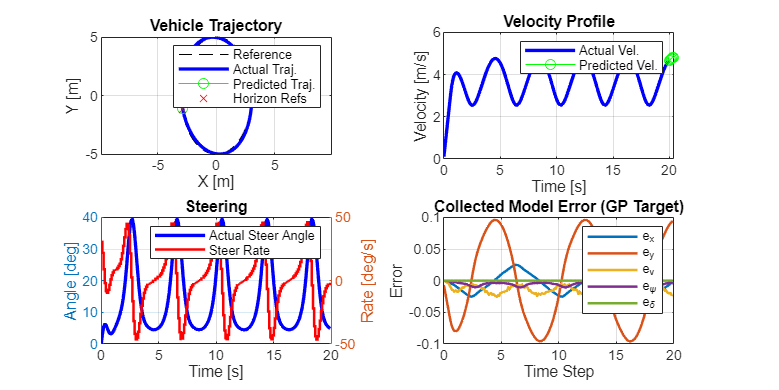

% Collecting model error data using baseline MPC.

tic;
data = runDataCollectionSimulation(p, I, reference_path);

data_collection_time = toc;

% Display collection results in a single block
fprintf(['   Data collection completed!\n' ...
         '   - Number of samples collected: %d\n' ...
         '   - Input dimension: %d\n' ...
         '   - Output dimension: %d\n' ...
         '   - Collection time: %.2f seconds\n\n'], ...
         size(data.X, 1), size(data.X, 2), size(data.Y, 2), data_collection_time);

   Data collection completed!
   - Number of samples collected: 200
   - Input dimension: 7
   - Output dimension: 5
   - Collection time: 39.61 seconds



### **1.4 Save Collected Data**

Finally, the collected data structure (`data`), which contains the GP input and target pairs, is saved to a `.mat` file. This file will be loaded in the next part of the tutorial to train our GP models.

% 1.4 Saving collected data...
save('gp_mpc_data.mat', 'data', 'p', 'I');
fprintf('   Data saved to gp_mpc_data.mat file.\n\nPART 1 completed! ✓\n\n');

   Data saved to gp_mpc_data.mat file.

PART 1 completed! ✓



# **PART 2: GP MODEL TRAINING**

Now that we have collected data on the model's predictive errors, we will use it to train a set of Gaussian Process models. The goal of the GP is to learn the underlying pattern of the model mismatch, $d = f_{real}(x, u) - f_{pred}(x, u)$. By learning this function, the GP can provide corrections to the MPC's predictions, leading to more accurate control. Here, we intentionally impose the model uncertainties (See red hightlighted parts)

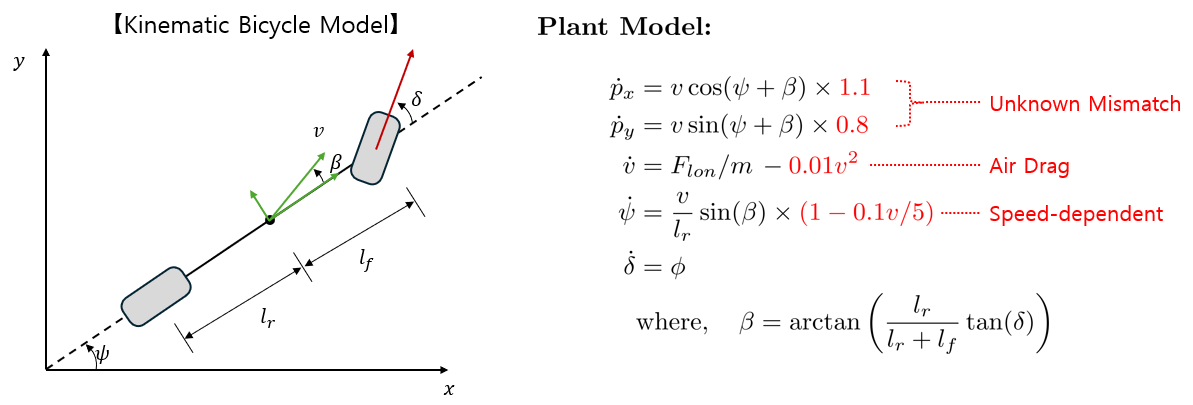

### **2.1 GP Training Parameters**

We set the parameters for the GP training process. A key parameter is `p.num_gp_points`, which defines the size of the data subset to be used for training. Because GP training complexity scales cubically with the number of data points, using a smaller, representative subset is crucial for computational efficiency. We also define the `train_ratio` to split our collected data into a training set and a validation set.

% 'PART 2: GP MODEL TRAINING : Train GP models using collected error data.
% 2.1 GP Training Parameters
p.num_gp_points = 50;  % Subset size for efficient training
train_ratio = 0.8;      % Training/validation split ratio

fprintf(['   - Number of GP training data points: %d\n' ...
         '   - Training/validation data ratio: %.1f/%.1f\n\n'], ...
         p.num_gp_points, train_ratio, 1-train_ratio)

   - Number of GP training data points: 50
   - Training/validation data ratio: 0.8/0.2



### **2.2 Training Data Preparation**

First, we split the collected data into training and validation sets according to the `train_ratio`. The training data is used to learn the GP models, while the validation data is used to evaluate their performance on unseen samples.

Next, we use the `selectSubsetOfData` function, which employs k-means clustering. This technique selects `p.num_gp_points` data points whose centroids are representative of the entire training dataset's distribution. This ensures we train our models on a small but informative subset, which is a common and effective approach for scaling GPs.

% 2.2 Training Data Preparation
[train_data, val_data] = utilityFunctions('prepareTrainingData', data, I, train_ratio);

Data ready:
  - Total samples: 200
  - Training samples (pre-split): 160
  - Validation samples: 40


% Data subset selection using K-means
train_data_subset = gpFunctions('selectSubsetOfData', train_data, p.num_gp_points);
fprintf('   Subsampling completed: %d -> %d samples\n\n', size(train_data.X, 1), size(train_data_subset.X, 1));

   Subsampling completed: 160 -> 50 samples



### **2.3 GP Model Training**

With the prepared data subset, we train the GP models. We train a separate GP for each of the five state error dimensions $e_x, e_y, e_v, e_{\psi}, e_{\delta}$. A GP models the error $d(X)$ as a sample from a multivariate normal distribution: $d(X) \sim \mathcal{GP}(m(X), k(X, X'))$ where $m(X)$ is the mean function (assumed to be zero) and $k(X, X')$ is the kernel function.

We use the popular Squared Exponential (SE) kernel: $k(x_i, x_j) = \sigma_f^2 \exp\left(-\frac{1}{2}(x_i - x_j)^T \Lambda^{-1} (x_i - x_j)\right)$ where the hyperparameters $\theta = \{\Lambda, \sigma_f^2, \sigma_n^2\}$ (length-scales $\Lambda$, signal variance $\sigma_f^2$, and noise variance $\sigma_n^2$) are learned by minimizing the Negative Log Marginal Likelihood (NLML). This optimization is handled inside the `trainGPModels` function.

% 2.3 GP Model Training
tic;
gp_models = gpFunctions('trainGPModels', train_data_subset, I);

  - Training GP model for state 1 error...
    -> Optimization complete. Signal_std=0.033, Noise_std=0.000
  - Training GP model for state 2 error...
    -> Optimization complete. Signal_std=0.090, Noise_std=0.000
  - Training GP model for state 3 error...
    -> Optimization complete. Signal_std=0.010, Noise_std=0.000
  - Training GP model for state 4 error...
    -> Optimization complete. Signal_std=0.009, Noise_std=0.000
  - Training GP model for state 5 error...
    -> Optimization complete. Signal_std=0.000, Noise_std=0.000


gp_training_time = toc;

% Display training results in a single block
fprintf(['   GP model training completed!\n' ...
         '   - Number of trained models: %d (one per state error)\n' ...
         '   - Training time: %.2f seconds\n\n'], ...
         length(gp_models), gp_training_time);

   GP model training completed!
   - Number of trained models: 5 (one per state error)
   - Training time: 1.34 seconds



### **2.4 & 2.5 Model Validation and Visualization**

After training, it is crucial to validate the models. The `validateGPModels` function plots the GP's predictions against the true error values from the held-out validation set. 

The `visualizeGPPredictions` function shows how the GP predictions and their uncertainty evolve over a time sequence from the data, providing insight into the model's dynamic performance.

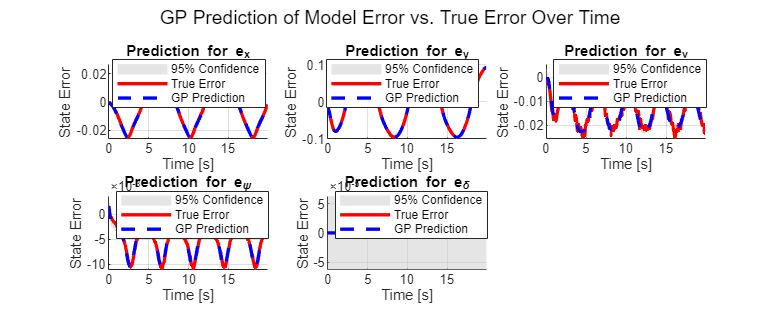

% 2.4 Model Validation
% visualizationFunctions('validateGPModels', gp_models, val_data, I);
% 2.5 Prediction Performance Visualization
visualizationFunctions('visualizeGPPredictions', gp_models, data, I, p);

**NOTE: **In this example, we're not actively adding noise, which results in very narrow confidence intervals in the graph over time. Feel free to play around with it.

### **2.6 Save Trained Models**

% 2.6 Save trained models
save('gp_models.mat', 'gp_models');
fprintf('   GP models saved to gp_models.mat file.\n\nPART 2 completed! ✓\n\n');

   GP models saved to gp_models.mat file.

PART 2 completed! ✓



# **PART 3: GP-MPC IMPLEMENTATION**

This is the final and most important part of the tutorial. We will now integrate the GP models trained in Part 2 into the Model Predictive Controller. This creates a **"GP-MPC" **that leverages the learned model of the system's error dynamics. Its state predictions will be more accurate, and it can explicitly account for uncertainty in its decisions. We will then run both the baseline MPC and our new GP-MPC to compare their performance and demonstrate the benefits of this approach.

### **3.1 GP-MPC Parameters**

We first define a few new parameters that are specific to the GP-MPC formulation.

- `p.beta`: This parameter determines the confidence level for the chance constraints. It's a scaling factor for the standard deviation of the GP's prediction. A larger $\beta$ makes the controller more conservative and less likely to violate constraints under uncertainty. A value of $\beta=2.0$ corresponds to approximately a 95.4% confidence level.

- `p.variance_weigh``t`: This is a weight for a new term in the MPC's cost function that penalizes state uncertainty. This encourages the controller to guide the vehicle towards regions where the GP model is more certain about its predictions.

- `p.gp_enable_mask`: This is a binary mask that allows us to selectively apply the GP correction to specific states. In this tutorial, we will only correct the $x$ and $y$ position states, as they are most critical for path tracking.

%PART 3: GP-MPC IMPLEMENTATION
% Chance constraint parameter (higher = more conservative)
p.beta = 2.0;  % 95.4% confidence level

% Uncertainty avoidance weight in cost function
p.variance_weight = 0.05;

% GP enable mask (which states to correct with GP)
p.gp_enable_mask = [1; 1; 0; 0; 0];  % Only x, y position errors

% Display GP-MPC parameters in a single block
fprintf(['   - Beta (chance constraint strength): %.1f (%.1f%% confidence)\n' ...
         '   - Variance weight: %.3f\n' ...
         '   - GP enable mask: [%s]\n' ...
         '     (1: GP correction applied, 0: not applied)\n\n'], ...
         p.beta, 100*(1-2*normcdf(-p.beta)), p.variance_weight, sprintf('%d ', p.gp_enable_mask));

   - Beta (chance constraint strength): 2.0 (95.4% confidence)
   - Variance weight: 0.050
   - GP enable mask: [1 1 0 0 0 ]
     (1: GP correction applied, 0: not applied)



### **3.2 Controller Simulations**

We will now run two simulations to facilitate a direct performance comparison. First, we run the GP-MPC controller. Second, we run the baseline MPC controller on the exact same task.

The core difference lies in the dynamics model used for prediction inside the controller.

- **Baseline MPC Dynamics**: The controller uses a deterministic model: $x_{k+1} = f(x_k, u_k)$.

- **GP-MPC Dynamics**: The controller uses the GP to augment the baseline model. The state $x_k$ is now a probability distribution. The mean of the state is propagated using the mean of the GP's prediction: $\bar{x}_{k+1} = f(\bar{x}_k, u_k) + B_{d} \mu_{GP}(\bar{x}_k, u_k)$.

This modification allows the GP-MPC to anticipate and counteract the systematic errors of its internal model.

      [GP-MPC] Simulation loop started...
         -> GP-MPC: 50 / 200 steps completed...
         -> GP-MPC: 100 / 200 steps completed...
         -> GP-MPC: 150 / 200 steps completed...


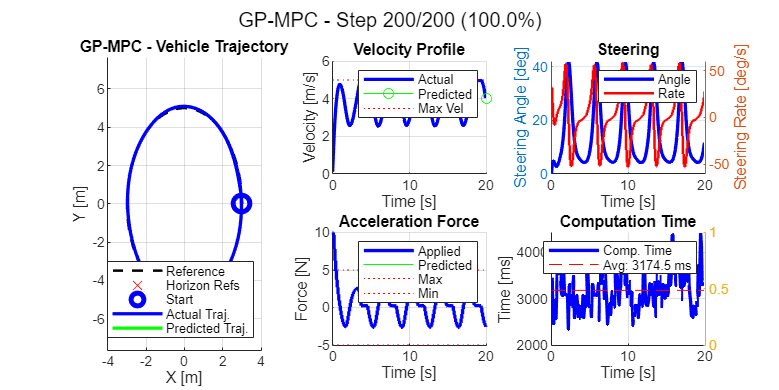

         -> GP-MPC: 200 / 200 steps completed...
      [GP-MPC] Simulation complete. Average computation time: 3174.47 ms


% 3.2 Controller Simulations
% Run GP-MPC simulation
tic;
results_gp = runControllerSimulation(p, I, reference_path, gp_models, 'GP-MPC');

      [Baseline-MPC] Simulation loop started...
         -> Baseline-MPC: 50 / 200 steps completed...
         -> Baseline-MPC: 100 / 200 steps completed...
         -> Baseline-MPC: 150 / 200 steps completed...
         -> Baseline-MPC: 200 / 200 steps completed...
      [Baseline-MPC] Simulation complete. Average computation time: 143.79 ms


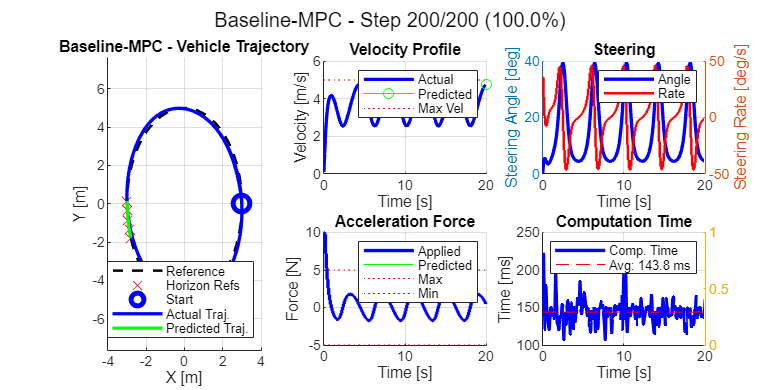

gp_mpc_time = toc;

% Run Baseline MPC simulation
tic;
results_base = runControllerSimulation(p, I, reference_path, [], 'Baseline-MPC');

base_mpc_time = toc;


### **3.3 Performance Comparison**

This is the final analysis step where we visualize the results and quantify the performance improvement. The GP-MPC's formulation differs from the baseline MPC in two key ways:

- **Objective Function**: The GP-MPC cost function includes an extra term, $w_{var} \cdot \text{trace}(\Sigma_k)$, which penalizes the cumulative variance $\Sigma_k$ of the predicted state trajectory. This encourages the controller to remain in regions of high certainty.

- **Constraints**: State limits are formulated as "chance constraints," which require the probability of satisfying the constraint to be above a certain threshold (e.g., 95.4%). These are converted to deterministic constraints using the GP's predictive mean and variance: $\bar{x}_k - \beta \cdot \sigma_k \ge x_{min}$ and $\bar{x}_k + \beta \cdot \sigma_k \le x_{max}$

We will compare the controllers based on the lateral tracking error (measured as Root Mean Square Error, RMSE) and the average computation time per step.

% 3.3 Performance Comparison
fprintf('3.3 Comparing performance and visualizing results...\n');

3.3 Comparing performance and visualizing results...


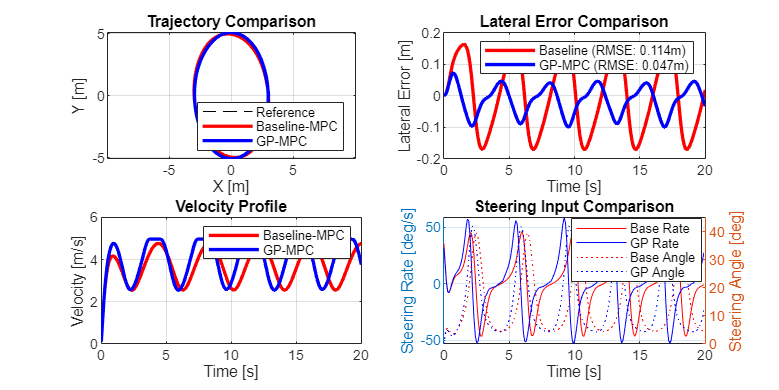

visualizationFunctions('visualizeAndCompareResults', p, I, reference_path, results_gp, results_base);


% Calculate and display performance metrics
lat_err_base = visualizationFunctions('calculateLateralError', results_base.states, reference_path);
lat_err_gp = visualizationFunctions('calculateLateralError', results_gp.states, reference_path);

rmse_base = rms(lat_err_base);
rmse_gp = rms(lat_err_gp);
improvement = (rmse_base - rmse_gp) / rmse_base * 100;

% Display performance metrics in a single block
fprintf(['\n   Performance metrics:\n' ...
         '   - Baseline MPC lateral RMSE: %.4f m\n' ...
         '   - GP-MPC lateral RMSE: %.4f m\n' ...
         '   - Performance improvement: %.1f%%\n' ...
         '   - Baseline MPC average computation time: %.2f ms\n' ...
         '   - GP-MPC average computation time: %.2f ms\n\n' ...
         'PART 3 completed! ✓\n\n'], ...
         rmse_base, rmse_gp, improvement, mean(results_base.comp_times)*1000, mean(results_gp.comp_times)*1000);


   Performance metrics:
   - Baseline MPC lateral RMSE: 0.1142 m
   - GP-MPC lateral RMSE: 0.0465 m
   - Performance improvement: 59.3%
   - Baseline MPC average computation time: 143.79 ms
   - GP-MPC average computation time: 3174.47 ms

PART 3 completed! ✓



**NOTE: **The optimization solver used in this example is ***'fmincon'***. The computation time is not appropriate for real-world driving; you will need to use a different solver or post-processing such as building in C/C++, and you can see that **GP-MPC's** computation is 2-3 times slower compared to the original nonlinear problem.

### **TUTORIAL SUMMARY**

total_time = data_collection_time + gp_training_time + gp_mpc_time + base_mpc_time;

% Display the final summary content in a single block
fprintf(['The entire tutorial has been completed successfully!\n\n' ...
         'Key results:\n' ...
         '   - Training data collected: %d samples\n' ...
         '   - GP models trained: %d models\n' ...
         '   - Tracking performance improvement: %.1f%%\n' ...
         '   - Confirmed that GP-MPC successfully compensates for model mismatch\n\n' ...
         '========================================================================\n'], ...
         size(data.X, 1), length(gp_models), improvement);

The entire tutorial has been completed successfully!

Key results:
   - Training data collected: 200 samples
   - GP models trained: 5 models
   - Tracking performance improvement: 59.3%
   - Confirmed that GP-MPC successfully compensates for model mismatch



## Function Helper

%% Local Functions 
% =========================================================================

function data = runDataCollectionSimulation(p, I, track)
    % Create an MPC problem
    model = mpcFunctions('generatePathTrackingProblem_modified', p, I);

    % Initializing Arrays for Storing Data
    simulatedStates = zeros(length(I.states), p.simLength + 1);
    appliedInputs = zeros(length(I.inputs), p.simLength);
    
    % Data [X, Y] for GP training
    X_data = zeros(p.simLength, p.nvar);
    Y_data = zeros(p.simLength, length(I.states));

    % Setting the initial state
    simulatedStates(:, 1) = [track.x(1), track.y(1), 0.1, track.heading(1), 0]';
    
    % MPC Initial Estimate
    predictedZ = zeros(model.nvar, model.N);
    predictedZ(I.inputs, :) = repmat([model.ub(I.FLon); 0], 1, model.N);
    model.x0 = reshape(predictedZ, [], 1);

    handles = []; % Plot handles

    % Main simulation loop
    for k = 1:p.simLength
        model.xinit = simulatedStates(:, k);
        nextPathPoints = pathFunctions('resamplePathForTracker', simulatedStates(:,k), I, track, p.timeStep, p.horizonLength);
        p_vec = [model.xinit; nextPathPoints(1,:)'; nextPathPoints(2,:)'];
        
        options = optimoptions('fmincon', 'Algorithm','sqp', 'Display','none', 'MaxIterations', 200);
        [z_opt, ~, exitflag] = fmincon(@(z) model.objective(z, p_vec), model.x0, ...
            [], [], [], [], model.lb, model.ub, @(z) model.nonlcon(z, p_vec), options);

        if exitflag < 1
            warning('FMINCON failed to converge at step %d.', k);
        end
        
        u_k = z_opt(I.inputs);
        x_k = simulatedStates(:, k);
        
        % Data collection: Predicted vs. actual state 
        z_stage1 = z_opt(1:p.nvar);
        x_pred_next = model.eq(z_stage1);
        x_real_next = vehicleDynamics('simulatePlant', x_k, u_k, p);
        error_k = x_real_next - x_pred_next;

        X_data(k, :) = [x_k; u_k]';
        Y_data(k, :) = error_k';
        
        simulatedStates(:, k+1) = x_real_next;
        appliedInputs(:, k) = u_k;
        model.x0 = z_opt;

        % Visualization (every 5 steps)
        if mod(k,5) == 0 || k == p.simLength
             predictedTraj = reshape(z_opt, p.nvar, p.horizonLength);
             handles = visualizationFunctions('plotSimData', k, p, I, track, simulatedStates, appliedInputs, predictedTraj, nextPathPoints, handles, Y_data);
             drawnow;
        end
        if mod(k, 50) == 0
            fprintf('      Simulation progress: %d / %d\n', k, p.simLength);
        end
    end
    
    data.X = X_data;
    data.Y = Y_data;
end

function results = runControllerSimulation(p, I, reference_path, gp_models, controller_type)
    model = mpcFunctions('generateMPCProblem', p, I, gp_models, controller_type);
    
    simStates = zeros(length(I.states), p.simLength + 1);
    simInputs = zeros(length(I.inputs), p.simLength);
    compTimes = zeros(p.simLength, 1);
    
    simStates(:, 1) = [reference_path.x(1), reference_path.y(1), 0.1, reference_path.heading(1), 0]';
    
    % MPC Initial Estimate
    predictedZ = zeros(model.nvar, model.N);
    predictedZ(I.inputs, :) = repmat([5; 0], 1, model.N);
    model.x0 = reshape(predictedZ, [], 1);
    
    handles = [];
    
    fprintf('      [%s] Simulation loop started...\n', controller_type);
    for k = 1:p.simLength
        tic;
        
        model.xinit = simStates(:, k);
        nextPathPoints = pathFunctions('resamplePathForTracker', simStates(:,k), I, reference_path, p.timeStep, p.horizonLength);
        p_vec = [model.xinit; nextPathPoints(1,:)'; nextPathPoints(2,:)'];
        
        % options = optimoptions('fmincon', 'Algorithm','sqp', 'Display','none', 'MaxIterations', 100, 'ConstraintTolerance', 1e-3, 'StepTolerance', 1e-8, 'UseParallel', true);
        options = optimoptions('fmincon', 'Algorithm','sqp', 'Display','none', 'MaxIterations', 100, 'ConstraintTolerance', 1e-3, 'StepTolerance', 1e-8, 'UseParallel', false);
        [z_opt, ~, exitflag] = fmincon(@(z) model.objective(z, p_vec), model.x0, ...
            [], [], [], [], model.lb, model.ub, @(z) model.nonlcon(z, p_vec), options);
        
        if exitflag < 1 && exitflag ~= -2
            warning('[%s] FMINCON failed to converge at step %d. (exitflag: %d)', controller_type, k, exitflag);
        end
        
        compTimes(k) = toc;
        u_k = z_opt(I.inputs);
        
        x_k = simStates(:, k);
        x_next = vehicleDynamics('simulatePlant', x_k, u_k, p);
        
        simStates(:, k+1) = x_next;
        simInputs(:, k) = u_k;
        model.x0 = z_opt;
        
        % Visualization update
        if mod(k, 5) == 0 || k == p.simLength
            predictedTraj = reshape(z_opt, p.nvar, p.horizonLength);
            handles = visualizationFunctions('plotRealtimeSimData', k, p, I, reference_path, simStates, simInputs, ...
                                        predictedTraj, nextPathPoints, handles, controller_type, compTimes);
            drawnow;
        end
        
        if mod(k, 50) == 0
            fprintf('         -> %s: %d / %d steps completed...\n', controller_type, k, p.simLength);
        end
    end
    
    results.name = controller_type;
    results.states = simStates;
    results.inputs = simInputs;
    results.comp_times = compTimes;
    fprintf('      [%s] Simulation complete. Average computation time: %.2f ms\n', controller_type, mean(compTimes)*1000);
end